# **Actividad 2: Robot Antropomórfico**

**Paola Rojas Domínguez** **A01737136**

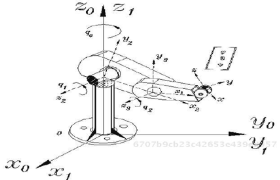

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 l3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%  rotacion_z= [cos(th1)  -sin(th1)   0 ;
%               sin(th1)   cos(th1)   0 ;
%               0                0    1];
%
%  rotacion_x= [1       0         0 ;
%               0  cos(90)  -sin(90);
%               0  sin(90)  cos(90)];
%
%  x_transf= [1  0  0;   %x +90
%             0  0 -1;
%             0  1  0];
% 
% 
%  transfor_1= rotacion_z*x_transf;

%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= [cos(th1)  0  sin(th1);
           sin(th1)  0 -cos(th1);
           0         1        0];

%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];
%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=   [cos(th3) -sin(th3)  0;
             sin(th3)  cos(th3)  0;
              0         0        1];
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Robot Antropormofico: A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    A(:,:,i)

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Robot Antropormofico: T', i_str))
    T(:,:,i)= simplify(T(:,:,i));
    T(:,:,i)

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %RO(:,:,i)
    %PO(:,:,i)
end

Robot Antropormofico: A1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Antropormofico: T1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Antropormofico: A2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Antropormofico: T2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Antropormofico: A3


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot Antropormofico: T3


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left(\sigma_{2}\right) & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{1}\\ \sin\left(\sigma_{2}\right) & \cos\left(\sigma_{2}\right) & 0 & \sin\left(\sigma_{2}\right)\,l_{3}+\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\sigma_{2}\right)\,l_{3}+\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right) \end{array}$$

%Calculamos el jacobiano lineal de forma diferencial
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%disp('Jacobiano lineal obtenido de forma diferencial'); jv_d
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);
V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-\sigma_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{4}-l_{3}\,\sigma_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{6}\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{3}-\sigma_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{4}-l_{3}\,\sigma_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sigma_{6}\\ \sigma_{2}\,\sigma_{3}+l_{3}\,\sigma_{1}\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{3}=\sigma_{5}\,l_{3}+\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}\\ \sigma_{4}=\sigma_{6}\,l_{3}+\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,l_{2}\\ \sigma_{5}=\cos\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{6}=\sin\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right) \end{array}$$

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); W

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}\right)$$